# Electromagnetic Analysis of Intelligent Reflecting Surface

clc;
clear all;
close all;

This example shows how to model the response of an intelligent reflecting surface (IRS) using full-wave electromagnetic simulation. The IRS, also known as the reconfigurable intelligent surface (RIS), large intelligent surface (LIS), or metasurface, has garnered significant interest in the wireless communication community. The IRS consists of a large array of subwavelength unit cell elements which can manipulate the phase, amplitude, polarization, or frequency of the incident signal. If an obstacle blocks the direct path between the base station (BS) and the user equipment (UE), the parasitic reflection of the IRS can provide an alternative path for signal transmission, as this figure shows. An external phase control mechanism can be integrated to control the reflection characteristics of the IRS.

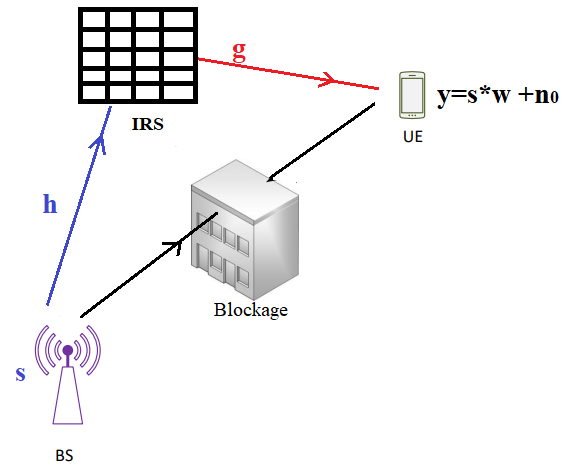

The inclusion of the RIS provides a two-segment indirect path to the signal traveling between the BS and the UE. The first segment covers the path between the BS and the IRS. The second segment covers the path between the IRS and the UE. The channel matrix of these two signal paths depends on the geometry and the electromagnetic reflection properties of the IRS.

The signal received at the UE is represented mathematically in [1] using this equation.

$r=sw+n_0=s\frac{\sqrt{G_rG_uG_tA_rA_u}}{4\pi}\sum_{n=1}^N \frac{\sqrt{\tilde{F}_n}R_n}{d_{tn}d_{rn}}e^\frac{-j2\pi(d_{tn}+d_{rn})}{\lambda}+n_0$,

where

- 
$$R=[R_1~R_2~......R_n]^T.$$


- $G_u$ is the embedded gain of the $n^{th}$ IRS element.

- $G_t$ is the embedded gain of the BS transmitter.

- $G_r$ is the embedded gain of the UE receiver.

- $F_n=F_n^tF_n^rF_{n}^{tx}F^{rx}_n$ is the product of the normalized power patterns of the BS, UE, and IRS.

- $d_t$ is the distance between the BS and the $n^{th}$ IRS element.

- $d_r$ is the distance between the UE and the $n^{th}$ IRS element.

- $A_r$ is the  effective aperture area of the UE.

- $A_u$ is the effective aperture area of the $n^{th}$ IRS element.

- $\lambda$ is the free-space wavelength.

For this example, assume that the IRS has $$N$$ unit cell elements. The complex reflection coefficient of the $n^{th}$ IRS element is denoted by $R_n=R^{mag}_n e^{j\tau_n}$.

The reflection coefficients of the IRS depend on these factors:

- Direction and polarization of the incoming signal towards the IRS.

- Direction and polarization of the outgoing signal from the IRS.

- Material properties and geometry of the IRS.

This example focuses on varying the incident signal configurations and determining the corresponding reflection characteristics.

Assume that $d_{tn}$ and $d_{rn}$ are in the far-field range. You can abstract the IRS as [infiniteArray](docid:antenna_ref#bvfg_q0-1) catalog element with a [planeWaveExcitation](docid:antenna_ref#bvj2_xq-1) model.

### Parameters

#### Grid 

grid_size=0.1;%in meters

#### IRS

pos_IRS=[0, 0, 2]; % location of the IRS
F0 = 28e9; %operational frequency
lambda = physconst("LightSpeed")/F0;
N_v=25; %Number of rows of reflecting units on the RIS
N_h=25; %Number of columns of reflecting units on the RIS
Gu_dBi = 9.03; % gain of reflecting unit see [2] and [1,Sec. IV and Table I]
Gu = 10^(Gu_dBi/10); %gain of reflecting unit in the linear scale
F_t_n=ones(N_v,N_h);%normalized radiation pattern from the IRS to the transmitter
F_r_n=ones(N_v,N_h);%normalized radiation pattern from the IRS to the receiver
D_h=lambda/2;%distance between elements
IRS_size=D_h*N_v;

#### Transmitter, see parameters in [1,Sec. IV and Table I]

Gt_dBi=21; %gain of the transmit antenna in dBi
Gt = 10^(Gt_dBi/10); %gain of the transmit antenna in the linear scale
F_tx_n=ones(N_v,N_h);% radiation patern of the transmit antenna to the n-th element
A_u=lambda^2/(4*pi);%aperture of the transmitt antenna
pos_tx=[5,-5,2];
Pt_dBm=30;%transmitt power in dBm
%k = 2*pi/lambda;

Incident wave Calculation

inc_loc=pos_tx-pos_IRS;%location of the incident wave relative to the IRS position
[phi_inc,theta_inc,radius_inc]=cart2sph(inc_loc(1),inc_loc(2),inc_loc(3));
elevation_inc = pi/2 + theta_inc; % rotate the emitter
%transforming from rad to degrees
phi_inc=rad2deg(phi_inc);
theta_inc=rad2deg(theta_inc);

#### Receiver, see parameters in [1,Sec. IV and Table I]

Gr_dBi=21; %gain of the receiver antenna
Gr = 10^(Gr_dBi/10); %gain of the receive antenna in the linear scale
F_rx_n=ones(N_v,N_h);% radiation patern of the receiver antenna to the n-th element
A_r= lambda^2/4/pi;
pos_rx_1=[4,2,0];
pos_rx_2=[4,1,0];
%k = 2*pi/lambda;


#### Fontsize

fontsize=15;

#### Observation grid in the xy plane

tx_size_img=2;%for depicting only
rx_size=1.7;
x_min=min([pos_tx(1),pos_IRS(1),pos_rx_1(1)])-3*min([tx_size_img,IRS_size,rx_size]);
x_max=max([pos_tx(1),pos_IRS(1),pos_rx_1(1)])+max([tx_size_img,IRS_size,rx_size]);
y_min=min([pos_tx(2),pos_IRS(2),pos_rx_1(2)])-max([tx_size_img,IRS_size,rx_size]);
y_max=max([pos_tx(2),pos_IRS(2),pos_rx_1(2)])+max([tx_size_img,IRS_size,rx_size]);

%the rows are in the y-direction
%the columns are in the x-direction
pos_obs=cell(ceil((x_max-x_min)/grid_size),ceil((y_max-y_min)/grid_size));

for i=1:ceil((x_max-x_min)/grid_size)
    for j=1:ceil((y_max-y_min)/grid_size)
        pos_obs{i,j}=[x_min+grid_size*i ...
                      y_min+grid_size*j ...
                      0];
    end
end

#### Depicting the Scenario

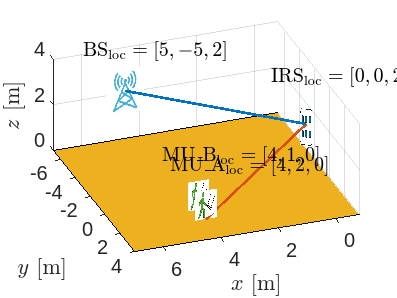

figure;
%depicting the MU
rot_az=20*pi/360;
img = imread('figures/MU.jpg');
[row,col]=size(img);
xImage = [pos_rx_1(1)-row/col*rx_size*cos(rot_az) pos_rx_1(1)+row/col*rx_size*cos(rot_az);...
          pos_rx_1(1)-row/col*rx_size*cos(rot_az) pos_rx_1(1)+row/col*rx_size*cos(rot_az)]; % The y data for the image corners

yImage = [pos_rx_1(2) pos_rx_1(2);...
          pos_rx_1(2) pos_rx_1(2)]; % The x data for the image corners


zImage = [pos_rx_1(3)+1.5*rx_size/2 pos_rx_1(3)+1.5*rx_size/2;...
          pos_rx_1(3) pos_rx_1(3)];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none'); hold on;
txt=strcat("$$\mathrm{MU\_A}_\mathrm{loc}=[",num2str(pos_rx_1(1)),",",num2str(pos_rx_1(2)),",",num2str(pos_rx_1(3)),"]$");
text(pos_rx_1(1)+rx_size,pos_rx_1(2)+rx_size,pos_rx_1(3)+2*rx_size,txt,'Interpreter','latex','FontSize',fontsize);

%second MU
xImage = [pos_rx_2(1)-row/col*rx_size*cos(rot_az) pos_rx_2(1)+row/col*rx_size*cos(rot_az);...
          pos_rx_2(1)-row/col*rx_size*cos(rot_az) pos_rx_2(1)+row/col*rx_size*cos(rot_az)]; % The y data for the image corners

yImage = [pos_rx_2(2) pos_rx_2(2);...
          pos_rx_2(2) pos_rx_2(2)]; % The x data for the image corners


zImage = [pos_rx_2(3)+1.5*rx_size/2 pos_rx_2(3)+1.5*rx_size/2;...
          pos_rx_2(3) pos_rx_2(3)];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none'); hold on;
txt=strcat("$$\mathrm{MU\_B}_\mathrm{loc}=[",num2str(pos_rx_2(1)),",",num2str(pos_rx_2(2)),",",num2str(pos_rx_2(3)),"]$");
text(pos_rx_2(1)+rx_size,pos_rx_2(2)+rx_size,pos_rx_2(3)+2*rx_size,txt,'Interpreter','latex','FontSize',fontsize);


%depicting the BS
rot_az=0*pi/360;
% rot_el=30*2*pi/360;

img = imread('figures/BS.jpg');
[row,col]=size(img);
xImage = [pos_tx(1)-row/col*tx_size_img*cos(rot_az) pos_tx(1)+row/col*tx_size_img*cos(rot_az);...
          pos_tx(1)-row/col*tx_size_img*cos(rot_az) pos_tx(1)+row/col*tx_size_img*cos(rot_az)]; % The y data for the image corners
yImage = [pos_tx(2) pos_tx(2);...
          pos_tx(2) pos_tx(2)]; % The x data for the image corners
zImage = [pos_tx(3)+tx_size_img pos_tx(3)+tx_size_img;...
          pos_tx(3) pos_tx(3)];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none');
txt=strcat("$\mathrm{BS}_\mathrm{loc}=[",num2str(pos_tx(1)),",",num2str(pos_tx(2)),",",num2str(pos_tx(3)),"]$");
text(pos_tx(1)+tx_size_img,pos_tx(2)+tx_size_img,pos_tx(3)+2*tx_size_img,txt,'Interpreter','latex','FontSize',fontsize);

xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
set(gca,'FontSize',fontsize);

%depicting the IRS
IRS_size=D_h*N_v*2;
IRS_scale=0.5;
rot_az=150*pi/360;
img = imread('figures/IRS.jpg');
xImage = [pos_IRS(1)-row/col*tx_size_img*cos(rot_az) pos_IRS(1)+row/col*tx_size_img*cos(rot_az);...
          pos_IRS(1)-row/col*tx_size_img*cos(rot_az) pos_IRS(1)+row/col*tx_size_img*cos(rot_az)]; % The X data for the image corners

yImage = [pos_IRS(2)+IRS_scale*IRS_size pos_IRS(2)-IRS_scale*IRS_size;...
          pos_IRS(2)+IRS_scale*IRS_size pos_IRS(2)-IRS_scale*IRS_size]; % The Y data for the image corners


zImage = [pos_IRS(3)+3*IRS_scale*col/row*IRS_size pos_IRS(3)+3*IRS_scale*col/row*IRS_size;...
          pos_IRS(3)-1*IRS_scale*col/row*IRS_size pos_IRS(3)-1*IRS_scale*col/row*IRS_size];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none');
txt=strcat("$\mathrm{IRS}_\mathrm{loc}=[",num2str(pos_IRS(1)),",",num2str(pos_IRS(2)),",",num2str(pos_IRS(3)),"]$");
text(pos_IRS(1)+2*IRS_size,pos_IRS(2)-10*IRS_size,pos_IRS(3)+2*IRS_size*col/row,txt,'Interpreter','latex','FontSize',fontsize);

%depicting the line from the BS to the IRS
plot3([pos_tx(1) pos_IRS(1)],[pos_tx(2) pos_IRS(2)], [pos_tx(3)+tx_size_img/2 pos_IRS(3)+IRS_size*2],'LineWidth',2);

%depicting the line from the IRS to the MU
plot3([pos_rx_1(1) pos_IRS(1)],[pos_rx_1(2) pos_IRS(2)], [pos_rx_1(3) pos_IRS(3)+IRS_size*2],'LineWidth',2);

%depicting the ground plane
rect=rectangle('Position',[min([pos_tx(1),pos_IRS(1),pos_rx_1(1)])-max([tx_size_img,IRS_size,rx_size])...
                           min([pos_tx(2),pos_IRS(2),pos_rx_1(2)])-max([tx_size_img,IRS_size,rx_size]) ...
                           max([pos_tx(1),pos_IRS(1),pos_rx_1(1)])-min([pos_tx(1),pos_IRS(1),pos_rx_1(1)])+2*max([tx_size_img,IRS_size,rx_size]) ...
                           max([pos_tx(2),pos_IRS(2),pos_rx_1(2)])-min([pos_tx(2),pos_IRS(2),pos_rx_1(2)])+2*max([tx_size_img,IRS_size,rx_size]) ...
                           ],'FaceColor',"#EDB120");


axis([min([pos_tx(1),pos_IRS(1),pos_rx_1(1)])-3*min([tx_size_img,IRS_size,rx_size]) ...
      max([pos_tx(1),pos_IRS(1),pos_rx_1(1)])+max([tx_size_img,IRS_size,rx_size])...
      min([pos_tx(2),pos_IRS(2),pos_rx_1(2)])-max([tx_size_img,IRS_size,rx_size]) ...
      max([pos_tx(2),pos_IRS(2),pos_rx_1(2)])+max([tx_size_img,IRS_size,rx_size])...
      min([pos_tx(3),pos_IRS(3),pos_rx_1(3)]) ...
      max([pos_tx(3),pos_IRS(3),pos_rx_1(3)])+max([tx_size_img,IRS_size,rx_size])]);


xlabel('$x$ [m]','Interpreter','latex');
ylabel('$y$ [m]','Interpreter','latex');
zlabel('$z$ [m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

view([-200 50])

## Configuring the IRS

We assume the IRS is oriented to the yz plane

Calculating the distances between the elements in the scenario: BS, IRS, MU, and observation points in the XY plane.

%calculating the spatial location of the IRS elements
pos_IRS_n=cell(N_v,N_h);%stores the position of the IRS elements
%distance from the transmitter to the IRS elements
d_t_n=zeros(N_v,N_h);
%distance from the receiver to the IRS
d_r_n_1=zeros(N_v,N_h);
d_r_n_2=zeros(N_v,N_h);
%distance from the observation points to the IRS elements
d_obs_n=zeros(N_v,N_h,ceil((x_max-x_min)/grid_size),ceil((y_max-y_min)/grid_size));

x=1;
y=1;
for i=1:N_v
    for j=1:N_h
        %nth-IRS element positions
        pos_IRS_n{i,j}=pos_IRS+(N_v/2-0.5-(i-1))*[0 0 1]*D_h+...
                               ((j-1)-N_h/2+0.5)*[0 1 0]*D_h;
        %nth-IRS element distance to the transmitter
        d_t_n(i,j)=norm(pos_IRS_n{i,j}-pos_tx);
        %nth-IRS element distance to the receiver
        d_r_n_1(i,j)=norm(pos_IRS_n{i,j}-pos_rx_1);
        d_r_n_2(i,j)=norm(pos_IRS_n{i,j}-pos_rx_2);
        %nth-Obs element distance to the observation point
        for x=1:ceil((x_max-x_min)/grid_size)
            for y=1:ceil((y_max-y_min)/grid_size)
                d_obs_n(i,j,x,y)=norm(pos_IRS_n{i,j}-pos_obs{x,y});
            end
        end
        %
        
    end
end


Calculating the CIR between the BS and the nth-elementIRS

%see [1, Eq. (2)]
h_t_n=sqrt(A_u*F_tx_n*F_t_n./(4*pi*d_t_n.^2)).*exp(-1i*2*pi*d_t_n/lambda);


Calculating the received signal by the MU at the BS with the observation point. In the following loop three steps are implemented per observation point:

- The CIR between the nth-element IRS and the observation point is calculated

- The IRS is optimally configured with [1, Eq. (9)]

- The coefficient w is calculated with [1, Eq. (7)]

- The received signal is calculated with [1, Eq. (7)]

g_obs_n=zeros(N_v,N_h,ceil((x_max-x_min)/grid_size),ceil((y_max-y_min)/grid_size));
w_xy=zeros(ceil((x_max-x_min)/grid_size),ceil((y_max-y_min)/grid_size));
R_temp=zeros(ceil((x_max-x_min)/grid_size),ceil((y_max-y_min)/grid_size));
w_xy_temp=zeros(ceil((x_max-x_min)/grid_size),ceil((y_max-y_min)/grid_size));
for x=1:ceil((x_max-x_min)/grid_size)
    for y=1:ceil((y_max-y_min)/grid_size)
        %CIR between the nth-element IRS and the
        % observation point; see [1, Eq. (4)]
        g_obs_n(:,:,x,y)=sqrt(A_u*F_rx_n*F_r_n./(4*pi*d_obs_n(:,:,x,y).^2)).*exp(-1i*2*pi*d_obs_n(:,:,x,y)/lambda);
        %optimally configuring the IRS; see  [1, Eq. (9)]
        R=conj(g_obs_n(:,:,x,y)).*conj(h_t_n)./abs(conj(g_obs_n(:,:,x,y)).*conj(h_t_n));
        %Calculating the w coeff
        F=F_tx_n.*F_t_n.*F_rx_n.*F_r_n;
        w_xy(x,y)=sqrt(Gr*Gu*Gt*A_r*A_u)/(4*pi)*sum(sum(sqrt(F).*R./(d_t_n.*d_r_n_1).*exp((-1i*2*pi*(d_t_n+d_r_n_1))/lambda)))+...
                  0.1*sqrt(Gr*Gu*Gt*A_r*A_u)/(4*pi)*sum(sum(sqrt(F).*R./(d_t_n.*d_r_n_2).*exp((-1i*2*pi*(d_t_n+d_r_n_2))/lambda)));

    end
end

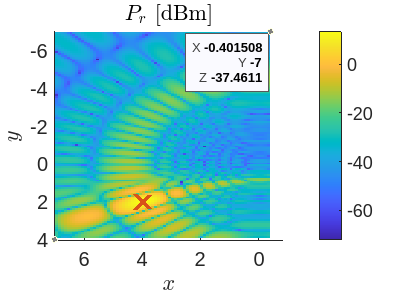

figure;
[X,Y] = meshgrid(x_min:grid_size:(x_max),y_min:grid_size:y_max-grid_size); hold on
s=surf(X',Y',20*log10(abs(w_xy)) + 30+Pt_dBm);
s.EdgeColor = 'none';

plot3(pos_rx_1(1),pos_rx_1(2),max(20*log10(abs(w_xy)))+ 30+Pt_dBm,'x','Color',"#D95319",'LineWidth',4,'MarkerSize',15);

xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$P_r$ [dBm]','Interpreter','latex');
set(gca,'FontSize',fontsize);
title({'$P_r$ [dBm]'},'Interpreter','latex')
colorbar
axis([min([pos_tx(1),pos_IRS(1),pos_rx_1(1)])-3*min([tx_size_img,IRS_size,rx_size]) ...
      max([pos_tx(1),pos_IRS(1),pos_rx_1(1)])+max([tx_size_img,IRS_size,rx_size])...
      min([pos_tx(2),pos_IRS(2),pos_rx_1(2)])-max([tx_size_img,IRS_size,rx_size]) ...
      max([pos_tx(2),pos_IRS(2),pos_rx_1(2)])+max([tx_size_img,IRS_size,rx_size])...
      min([min(20*log10(abs(w_xy)) + 30+Pt_dBm),min(20*log10(abs(w_xy)) + 30+Pt_dBm),min(20*log10(abs(w_xy)) + 30+Pt_dBm)]) ...
      max([max(20*log10(abs(w_xy)) + 30+Pt_dBm),max(20*log10(abs(w_xy)) + 30+Pt_dBm),max(20*log10(abs(w_xy)) + 30+Pt_dBm)])]);

view([-180 90]);

% view([-200 50])

You can do this analysis by using alternate infinite array configurations and different unit cell element to achieve desired IRS channel matrix behavior. Based on the phase of the reflection coefficients, the signal at the receiver's end can be constructively/destructively interfered to enhance/reduce the received signal strength in a specific observation direction.

## Further Exploration

Using the full-wave electromagnetic solution of Maxwell's equations from Antenna Toolbox™, you can perform a similar analysis with different IRS configurations constructed from the `infiniteArray` and `planeWaveExcitation` objects to design a physics-based smart propagation environment. The geometry of an IRS can be further integrated with Communication Toolbox™ and Optimization Toolbox™ software to obtain an accurate, physics-based characterization of IRS-aided wireless communication scenarios.

## Reference

[1] Cui, Yaoshen, Haifan Yin, Li Tan, and Marco Di Renzo., " A 3D Positioning-based Channel Estimation Method for RIS-aided mmWave Communications." arXiv:2203.14636 (April 21, 2022). [https://doi.org/10.48550/arXiv.2203.14636](https://doi.org/10.48550/arXiv.2203.14636).

*Copyright 2022 The MathWorks, Inc.*